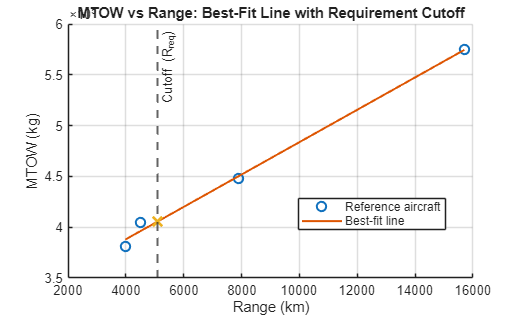

% Best-fit line (linear regression) + cutoff at required range
% Order: [747-8F, A380-800, An-124-100, C-5M, 787-10]

R = [7900 15700 4500 3980 ];          % Range (km)
W = [447700 575000 405000 381000 ];  % MTOW (kg)
DoStop = true;
if DoStop == true
    stop = 2;
else
    stop = 1;
end
Rreq = 10186/stop;                               % requirement (km)

p = polyfit(R, W, 1);                       % W = p(1)*R + p(2)
MTOW_est = polyval(p, Rreq);

Rline = linspace(min(R), max(R), 300);
Wfit  = polyval(p, Rline);

figure; grid on; hold on;
plot(R, W, 'o', 'MarkerSize', 7, 'LineWidth', 1.5);
plot(Rline, Wfit, '-', 'LineWidth', 1.5);
xline(Rreq, '--', 'Cutoff (R_{req})', 'LineWidth', 1.5);
plot(Rreq, MTOW_est, 'x', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('Range (km)'); ylabel('MTOW (kg)');
title('MTOW vs Range: Best-Fit Line with Requirement Cutoff');
legend('Reference aircraft','Best-fit line','Location','best');

fprintf('Best-fit MTOW at Rreq = %.0f km: %.0f kg\n', Rreq, MTOW_est);

Best-fit MTOW at Rreq = 5093 km: 405540 kg



% wokring out fuel fractions
A=0.97; C=-0.06;
OEWfrac = A*MTOW_est^C; 
OEW = OEWfrac*MTOW_est;

% Primary inputs
E_hr = 0.75;   M = 0.85;   LDmax = 18;

fw=0.970; fc=0.985; fl=0.995; K=1.06; % Raymer segment fracs + reserve

Ccr_hr=0.50; Clo_hr=0.40; eta=0.90; % Raymer HBTF TSFC (1/hr) + modern tweak

Ccr_hr=eta*Ccr_hr;  Clo_hr=eta*Clo_hr;

a_ms = 295; % speed of sound ~35kft (m/s)
V_ms = M*a_ms; % cruise TAS (m/s)
R_m  = Rreq*1000; % range (m)

LDcr = 0.866*LDmax; % Raymer jet cruise L/D

fcr = exp(-(R_m)*(Ccr_hr/3600)/(V_ms*LDcr)); % cruise fraction
flo = exp(-(E_hr*3600)*(Clo_hr/3600)/(LDmax)); % loiter fraction

WendW0 = fw*fc*fcr*flo*fl;
FuelFrac = K*(1 - WendW0);  Fuel = FuelFrac*MTOW_est;

Payload = MTOW_est - OEW - Fuel % "available payload" (no crew allowance)

Payload = 1.3647e+05

ZFW = MTOW_est - Fuel;  ZFWf = ZFW/MTOW_est;

fprintf("OEW=%.0f (%.3f), Fuel=%.0f (%.3f), Payload=%.0f (%.3f), ZFW=%.0f (%.3f)\n", ...
    OEW, OEWf, Fuel, FuelFrac, Payload, Payload/MTOW_est, ZFW, ZFWf);

OEW=181269 (0.442), Fuel=87798 (0.216), Payload=136473 (0.337), ZFW=317742 (0.784)
